clear all
close all

# Trajectory Generation (drones formation)

Starting from a grid at z=0, 'n' drones need to form a circle-shaped formation at z=10. The trajectories must satisfy also zero speed at arrival, min and max acceleration rates, and collision avoidance constraints. The vehicles need to arrive at destination at the same time.

You can change the number of nodes for each trajectory, N, and the number of vehicles involved in the mission, n. 

I would run the example with fixed N=4 and varying number of vehicles, e.g., n=5, 10, 25. The complexity grows up quite quickly. My computational times are t=1.3s, 4s, and 61s, respectively.

## Load Parameters

CONSTANTS.N = 5;
N = CONSTANTS.N;

% Define the number of vehicles
CONSTANTS.n = 25; 
n = CONSTANTS.n;

% Define the radius of the circle
r = 20;

% Compute the angles of the points
angles = linspace(0, 2*pi, n+1);
angles = angles(1:end-1);
p = randperm(n);
angles = angles(p);

% Compute the coordinates of the points
xcirc = r*cos(angles);
ycirc = r*sin(angles);

% Define the size of the square
size = 40;

% Compute the coordinates of the points
xsquare = linspace(-size/2, size/2, ceil(sqrt(n)));
ysquare = linspace(-size/2, size/2, ceil(sqrt(n)));
[X, Y] = meshgrid(xsquare, ysquare);


CONSTANTS.fin = zeros(n,6);
CONSTANTS.init = zeros(n,6);
des_alt = 10;
for i = 1 : n
    CONSTANTS.fin(i,:) = [xcirc(i);ycirc(i);des_alt;0;0;0]';
    CONSTANTS.init(i,:) = [X(i);Y(i);0;0;0;0]';
end     

CONSTANTS.umax = 1;
CONSTANTS.mindist = 0.1;

## Initial guess

for i = 1 : n
    x1(i,:) = linspace(CONSTANTS.init(i,1),CONSTANTS.fin(i,1),N+1);
    x2(i,:) = linspace(CONSTANTS.init(i,2),CONSTANTS.fin(i,2),N+1);
    x3(i,:) = linspace(CONSTANTS.init(i,3),CONSTANTS.fin(i,3),N+1);
    x4(i,:) = linspace(CONSTANTS.init(i,4),CONSTANTS.fin(i,4),N+1);
    x5(i,:) = linspace(CONSTANTS.init(i,5),CONSTANTS.fin(i,5),N+1);
    x6(i,:) = linspace(CONSTANTS.init(i,6),CONSTANTS.fin(i,6),N+1);
    u1(i,:) = zeros(N+1,1);
    u2(i,:) = zeros(N+1,1);
    u3(i,:) = zeros(N+1,1);
    T = 10;
    x0(i,:) = [x1(i,:) x2(i,:) x3(i,:) x4(i,:) x5(i,:) x6(i,:) u1(i,:) u2(i,:) u3(i,:) T];
end

## Linear Constraints and UL Bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

## Optimize

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',3000000);
tic
[x,fval] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 59.197612 seconds.


## Plot

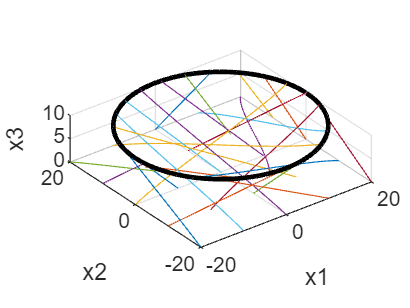

N = CONSTANTS.N;

%% Grab Trajectories

N = CONSTANTS.N;
for i = 1 : CONSTANTS.n
    x1(i,:) = x(i,1:N+1);
    x2(i,:) = x(i,N+2:2*N+2);
    x3(i,:) = x(i,2*N+3:3*N+3);
    x4(i,:) = x(i,3*N+4:4*N+4);
    x5(i,:) = x(i,4*N+5:5*N+5);
    x6(i,:) = x(i,5*N+6:6*N+6);
    u1(i,:) = x(i,6*N+7:7*N+7);
    u2(i,:) = x(i,7*N+8:8*N+8);
    u3(i,:) = x(i,8*N+9:9*N+9);
end

T = x(end,end);

%% Plot
time = 0:0.01:T;
figure
for i = 1 : CONSTANTS.n
    plot3(BernsteinPoly(x1(i,:),time),BernsteinPoly(x2(i,:),time),BernsteinPoly(x3(i,:),time)); hold on
end
xlabel('x1'); ylabel('x2'); zlabel('x3')
grid on
axis equal


% Compute the angles of the points
angles = linspace(0, 2*pi, 1000);
angles = angles(1:end-1);
% Compute the coordinates of the points
xcircle = r*cos(angles);
ycircle = r*sin(angles);
zcircle = des_alt*ones(1,length(xcircle));
plot3(xcircle,ycircle,zcircle,'k','Linewidth',2);

## Cost Function

function J = costfun(x,CONSTANTS)
N = CONSTANTS.N; 
T = x(end,end);
J = T;
end

## Nonlinear Constraints

function [c,ceq] = nonlcon(x,CONSTANTS)
N = CONSTANTS.N;
T = x(end,end);
k=0;
[~,~,Diff] = BeBOT(N,T);
for i = 1 : CONSTANTS.n
    x1(i,:) = x(i,1:N+1);
    x2(i,:) = x(i,N+2:2*N+2);
    x3(i,:) = x(i,2*N+3:3*N+3);
    x4(i,:) = x(i,3*N+4:4*N+4);
    x5(i,:) = x(i,4*N+5:5*N+5);
    x6(i,:) = x(i,5*N+6:6*N+6);
    u1(i,:) = x(i,6*N+7:7*N+7);
    u2(i,:) = x(i,7*N+8:8*N+8);
    u3(i,:) = x(i,8*N+9:9*N+9);

    dyn1(i,:) = x1(i,:)*Diff - x4(i,:);
    dyn2(i,:) = x2(i,:)*Diff - x5(i,:);
    dyn3(i,:) = x3(i,:)*Diff - x6(i,:);
    dyn4(i,:) = x4(i,:)*Diff - u1(i,:);
    dyn5(i,:) = x5(i,:)*Diff - u2(i,:);
    dyn6(i,:) = x6(i,:)*Diff - u3(i,:) + 9.8*ones(1,N+1);
end


for i = 1 : CONSTANTS.n

    if i < CONSTANTS.n
        for j = i + 1 : CONSTANTS.n
            k = k+1;
            dist2veh(k,:) = (x1(i,:) - x1(j,:)).^2 + (x2(i,:) - x2(j,:)).^2;
        end
    end

end

dist = dist2veh(:);


for i = 1 : CONSTANTS.n

    const_ineq(i,:)=[u1(i,:)'-CONSTANTS.umax;-u1(i,:)'-CONSTANTS.umax;u2(i,:)'-CONSTANTS.umax;-u2(i,:)'-CONSTANTS.umax;-9.8+u3(i,:)'-CONSTANTS.umax;9.8-u3(i,:)'-CONSTANTS.umax]';
    const_eq(i,:)=[dyn1(i,:)';dyn2(i,:)';dyn3(i,:)';dyn4(i,:)';dyn5(i,:)';dyn6(i,:)'; ... 
        x1(i,1)-CONSTANTS.init(i,1);x2(i,1)-CONSTANTS.init(i,2);x3(i,1)-CONSTANTS.init(i,3); ...
        x4(i,1)-CONSTANTS.init(i,4);x5(i,1)-CONSTANTS.init(i,5);x6(i,1)-CONSTANTS.init(i,6); ...
        x1(i,end)-CONSTANTS.fin(i,1);x2(i,end)-CONSTANTS.fin(i,2);x3(i,end)-CONSTANTS.fin(i,3); ...
        x4(i,end)-CONSTANTS.fin(i,4);x5(i,end)-CONSTANTS.fin(i,5);x6(i,end)-CONSTANTS.fin(i,6); ...
        ]';
end

c = [const_ineq(:); -dist + CONSTANTS.mindist.^2];
%c = [const_ineq(:)];
ceq = const_eq(:);

end

## Functions:

function [tnodes,w,Dm] = BeBOT(N,T)
% derivative of a Bezier curve
% INPUT
% N: order of the curve
% T: tf-t0
% OUTPUT
% tnodes: equidistant time nodes
% w: integration weights
% Dm: differentiation matrix for Bernstein polynomials of order N 

% HOW TO USE:
% If Cp are the control points of the Bernstein polyomial (horizontal
% vector), then the integral from t0 to tf is Cp*w;
% If Cp are the control points of the Bernstein polyomial (horizontal vector), then the control points
% its derivative are Cpdot = Cp*Dm
% NOTE: Cpdot are control points of a Bernstein poly of order N. In order words, 
% degree elevation is performed on Dm

tnodes = linspace(0,T,N+1);
w = T/(N+1)*ones(N+1,1);
Dm = BernsteinDifferentiationMatrix(N,T)*DegElevMatrix(N-1,N);


end










function Dm = BernsteinDifferentiationMatrix(N,T)
% derivative of a Bezier curve
% INPUT
% N: order of the curve
% T: tf-t0
% OUTPUT
% Dm: differentiation matrix for Bernstein polynomials of order N 

% HOW TO USE:
% If Cp are the control points of the Bernstein polyomial, then the control points
% its derivative are Cpdot = Cp*Dm
% NOTE: Cpdot are control points of a Bernstein poly of order N-1. To
% obtain Cpdot of order N, degree elevation must be performed, i.e. Cpdot =
% Cp*Dm*DegElevMatrix(N-1,N)


Dm = -[N/T*eye(N); zeros(1,N)]+[zeros(1,N);N/T*eye(N)];

end





function E = DegElevMatrix(N,M)
% INPUT: N: Order of the curve to be elevated; M: order to which it has to
% be elevated;
% OUTPUT: Elevation matrix E. 
% HOW TO USE: Given a Bernstein poly of order N with control points cpN (row vector),
% the control points of the Bernstein poly degree elevated to order N,
% namely cpM (row vector) is given by cpM = cpN*E;

% Written by: Venanzio Cichella       

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



r = M-N;

for i = 1:1:N+1
    for j = 1:1:r+1
         E(i+j-1,i) = nchoosek_mod(N,i-1)*nchoosek_mod(r,j-1)/nchoosek_mod(M,i+j-2);
    end
end

E = E';


end






function binom = nchoosek_mod(N,k)
% This function produces the same output as MATLAB's nchoosek, but it's more efficient 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

binom = 1;
    for j = 1:k
        binom = binom*(N-(k-j));
        binom = binom/j;
    end
end






function  poly_t  = BernsteinPoly(Cp,t,t0,tf)

% INPUTS:
% Cp is a matrix n by N+1 (n: dimension of polynomial, N: order of polynomial) 
% t is a time vector
% OUTPUT:
% poly_t: n-dimensional polynomial evaluated at each time t

% if t is a scalar, it returns the value of Bernstein Poly at t in [t0,tf]
% if t0 and tf are not provided, it returns the value of Bernstein Poly at t in [0,1]

% Written by: Venanzio Cichella       

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



[~, N] = size(Cp);
N = N-1;

if length(t) > 1
    B = BernsteinMatrix_a2b(N,t)';
    poly_t = Cp*B;
else
    if ~exist('t0','var')
        B = BernsteinMatrix_a2b(N,t)';
        poly_t = Cp*B;
    else
        B = BernsteinMatrix_a2b(N,t,t0,tf)';
        poly_t = Cp*B;
    end
end


end







function b = BernsteinMatrix_a2b(N, t, tmin, tmax)

% Inputs: order N, time vector t = [t0 ... tm], no need for tmin and tmax.
% Output: b = [b0N(t0) b1N(t0) ... bNN(t0);
%              b0N(t1) b1N(t1) ... bNN(t1);
%              ...
%              b0N(tm) b1N(tm) ... bNN(tm);
% Use: If Cp is a row vector of N+1 control points,
%       the Nth order Bezier curve is given by xN=Cp*b';
% This function is used in BernsteinPoly

% Alternatively
% Inputs: order n, scalar time t', tmin and tmax
% Output: b = [b0n(t') b1n(t') ... bnn(t')]
% Use: If Cp is a row vector of N+1 control points,
%       the Nth order Bezier curve evaluated at t' is given by xn=Cp*b';
% Comment: This is more efficient but not as robust as de Casteljau
%           It works best for low-order curves

% Written by: Venanzio Cichella       

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if length(t) > 1
    tmax = t(length(t));
    tmin = t(1);
end

if ~exist('tmin','var')
    tmin = 0; tmax = 1;
end



% compute B(j+1) = binomial(n, j), j = 0..n
t = t';
B = ones(N+1, 1); 
for j = 1:ceil(N/2)
  B(j+1) = B(j)*(N+1-j)/j;
  B(N+1-j) = B(j+1);
end
% compute T(i, j) = (t(i)-tmin)^j, TT(i, j) = (tmax-t(i))^(N-j)
T = ones(length(t), N+1);
TT = ones(length(t), N+1);
% turn a row t into a column t so that 
% we can do diag(t)*T(:,j) by t.*T(:,j)
tp = reshape(t, length(t), 1)-tmin;
ttp = tmax - t;
% Compute binomial(N, j)*(t(i)-tmin)^j*(tmax-t(i))^(N-j)
for j = 1:N 
  T(:, j+1) = tp .* T(:, j); 
  T(:, j) = T(:, j) .* B(j);
 TT(:,N+1-j) = ttp .* TT(:,N+2-j);
end

% Compute binomial(N, j)*(t(i)-tmin)^j*(tmax-t(i))^(N-j)/((tmax-tmin)^N)
b =  T.*TT./((tmax-tmin)^N);

end